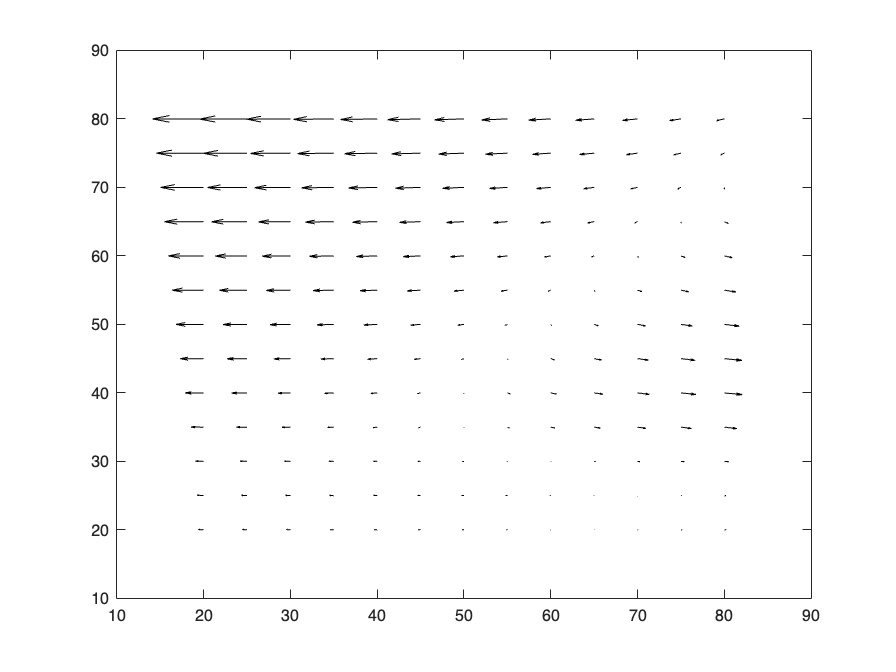

% sysnthesis rate in nM/min.
ode_params.ksynth =	1;

% rate params in min^-1.
ode_params.adeg	= 0.01;
ode_params.bdeg	= 0.04;
ode_params.acdc25 = 0.16;
ode_params.bcdc25 = 0.80;
ode_params.awee1 = 0.08;
ode_params.bwee1 = 0.40;

% Hill coefficients.
ode_params.ncdc25 = 11;
ode_params.nwee1 = 3.5;
ode_params.ndeg = 17;

% concentrations in nM.
ode_consts.EC50deg = 32;
ode_consts.EC50cdc25 = 35;
ode_consts.EC50wee1	= 30;

[cdk1_vals, cyc_vals] = meshgrid([20:5:80],[20:5:80]);

% get ODE functions.
ode_funcs = cdk1_cyclin_ode;

% get rate values at all points in the mesh.

dydt = ode_funcs.dydt_array(0, cat(3, cdk1_vals, cyc_vals), ode_params, ode_consts);
figure; zoom on;
quiver(cdk1_vals, cyc_vals, dydt(:, :, 1)', dydt(:, :, 2)', 'color', 'k');